symbolSpaceI = [1 1 0 0];
polarSymbolSpaceI = 2 * symbolSpaceI - 1;
symbolSpaceQ = [1 0 0 1];
polarSymbolSpaceQ = 2 * symbolSpaceQ - 1;

polarSymbolSpace = polarSymbolSpaceI + exp(1i*pi/2) * polarSymbolSpaceQ;
polarSymbolSpace = polarSymbolSpace/sqrt(2);

nSymbols = 1000000;
nBits = 2 * nSymbols;

SNRdB = 0:1:10;

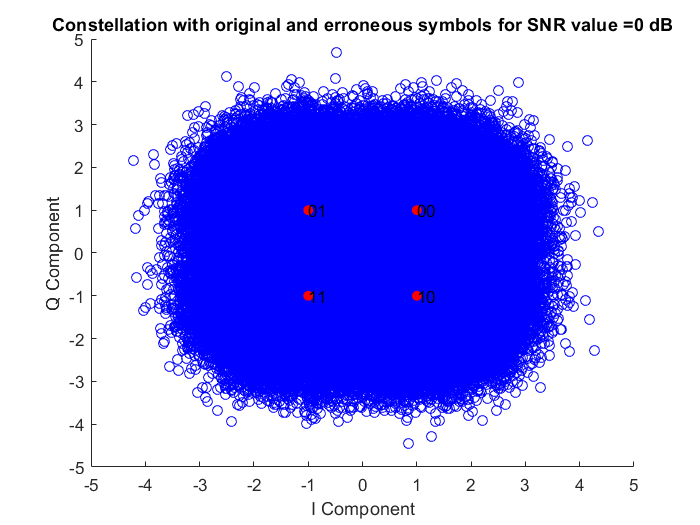

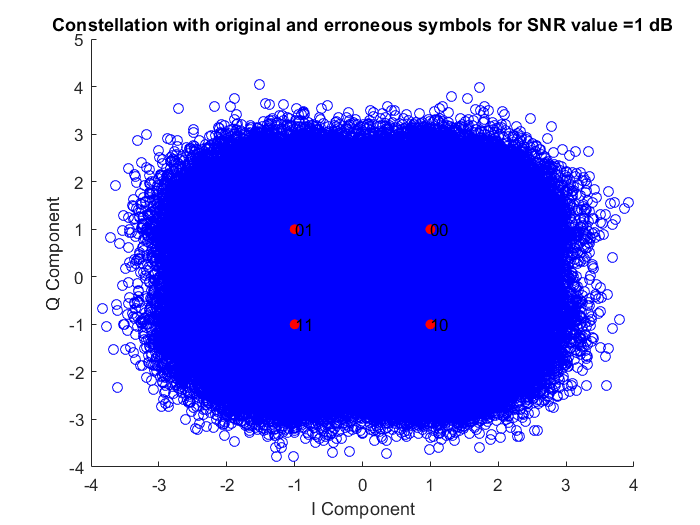

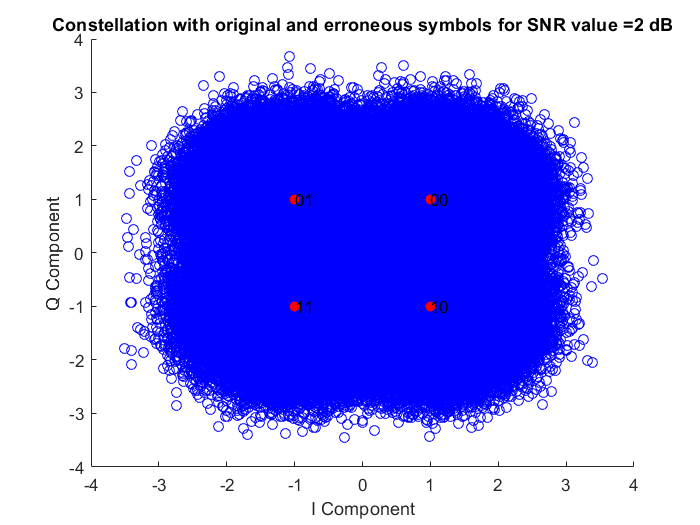

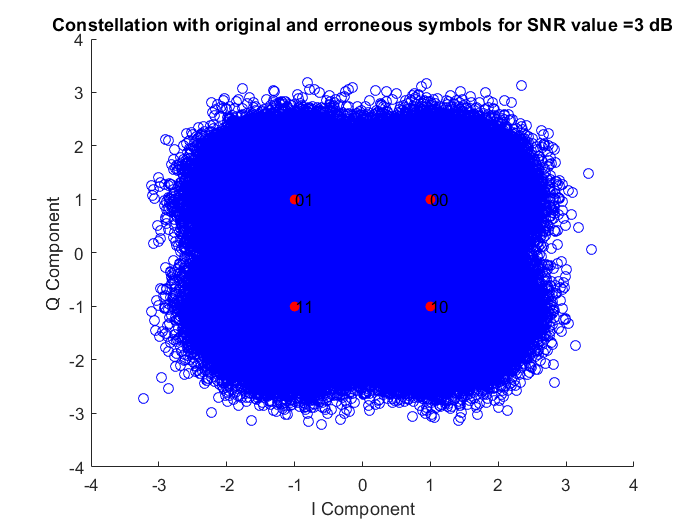

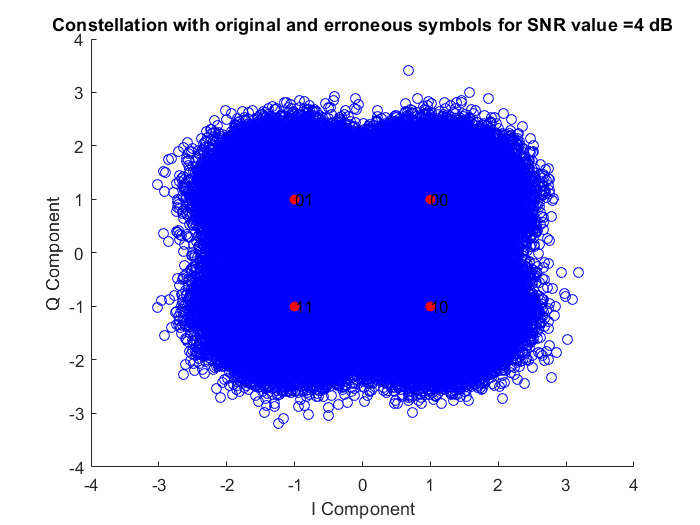

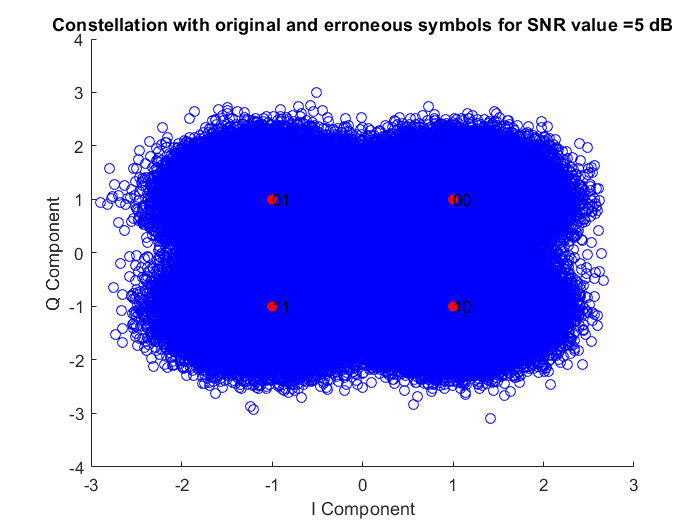

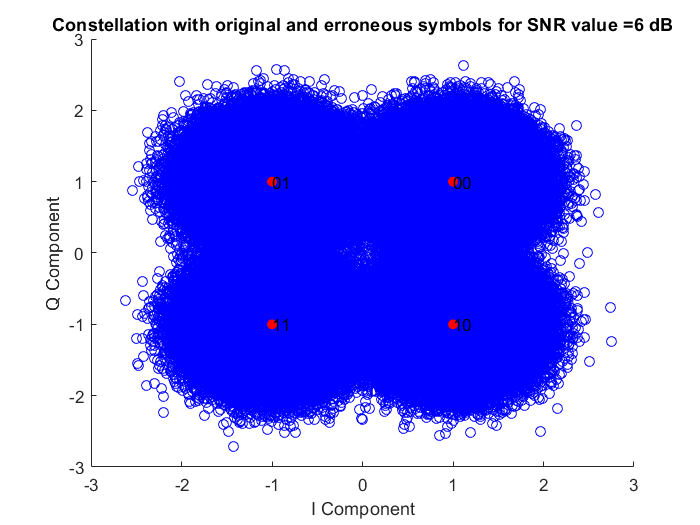

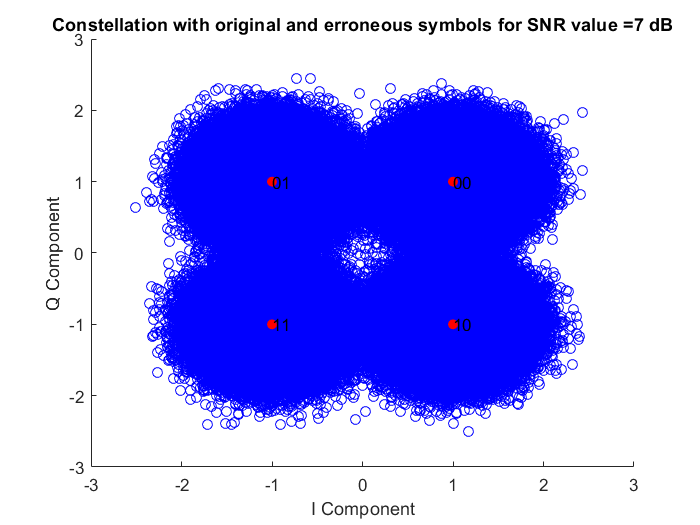

qpskGraySimulator(nSymbols, SNRdB);

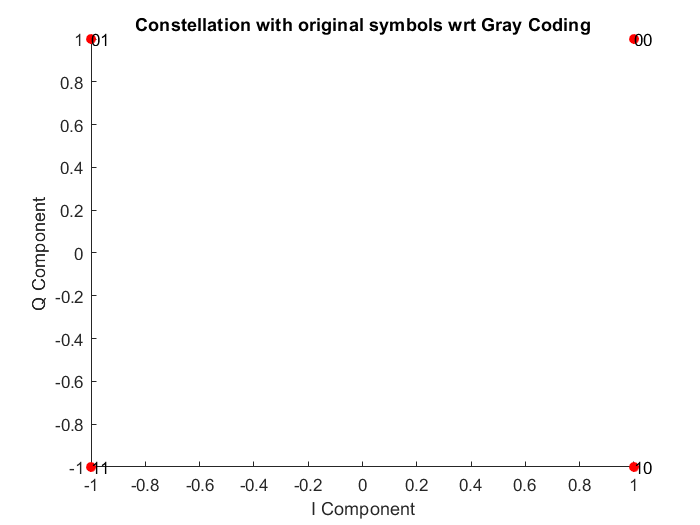

figure(length(SNRdB)+2);
scatter(polarSymbolSpaceI, polarSymbolSpaceQ, 'red', "filled");
text(polarSymbolSpaceI(1), polarSymbolSpaceQ(1), '00');
text(polarSymbolSpaceI(2), polarSymbolSpaceQ(2), '10');
text(polarSymbolSpaceI(3), polarSymbolSpaceQ(3), '11');
text(polarSymbolSpaceI(4), polarSymbolSpaceQ(4), '01');
plotTitle = strcat('Constellation with original symbols wrt Gray Coding');
title(plotTitle);
xlabel('I Component');
ylabel('Q Component');